## Test function: Generalization of the Brown function 1 - 10^3

% Dimension n (multiple of 2)
n = 10^3;  % 10^3;

% Initializations
f = @(x) 0;
f_plus = @(x) 0;
x0 = zeros(n, 1);

% Generalization of the Brown function 1
for j = 1 : (n - 2)/2
    f_1 = @(x) ((((x(2*j-1, :)) - 3).^2)/1000 - ...
        (x(2*j-1, :) - x(2*j, :)) + ...
        exp(20*(x(2*j-1, :) - x(2*j, :))));  % Brown function 1 (j=1)
    f_2 = @(x) (x(2*j-1, :) - 3);
    f_plus = @(x) f_plus(x) + f_2(x);
    f = @(x) f(x) + f_1(x);  % Generalization of the Brown function 1
end

% Starting point x0
for j = 1 : n
    if mod(j, 2) == 0
        x0(j) = -1;
    else
        x0(j) = 0;
    end
end
f = @(x) f(x) + (f_plus(x))^2;

% Expected solution
x_sol = ones(1, n)' .* 3;
for i = 1 : n
    if mod(i, 2) == 0
        x_sol(i) = 3.1498;  % arrotondato per eccesso
    end
end

% Gradient
gradf = @(x) generalized_brown_grad(x);

### Parameters 

load('forcing_terms.mat')

kmax = 1000;  % maximum number of iterations
step_k = 10;  % step between one iteration and the successive to memorize efficiently the orders fo convergence and the errors;
tolgrad = 1e-8;  % stopping criterion w.r.t. the norm of the gradient
alpha0 = 10;  % initial step-length
c1 = 1e-4;  % factor of the Armijo condition
rho = 0.1;  % fixed factor used for reducing alpha0
btmax = 800;  % ﻿maximum number of steps for updating alpha
parameters = table(kmax, step_k, tolgrad, alpha0, c1, rho, btmax)

parameters = 1×7 table
    kmax    step_k    tolgrad    alpha0      c1      rho    btmax
    ____    ______    _______    ______    ______    ___    _____

    1000      10       1e-08       10      0.0001    0.1     800 


## Steepest descent method - 10^3

[xk, fk, gradfk_norm, k, big_k, err_fseq, ordconv_seq, totalTimeCost, timeCostseq] = ...
    steepest_desc_bckt(x0, x_sol, f, gradf, alpha0, step_k, kmax, tolgrad, c1, rho, btmax);

*** Iterations overcome maximum number of iterations ***

results_0 = table(xk, x_sol);
head(results_0, 8)

ans = 8×2 table
      xk      x_sol 
    ______    ______

         3         3
    3.1498    3.1498
         3         3
    3.1498    3.1498
         3         3
    3.1498    3.1498
         3         3
    3.1498    3.1498


tail(results_0, 8)

ans = 8×2 table
      xk      x_sol 
    ______    ______

         3         3
    3.1498    3.1498
         3         3
    3.1498    3.1498
         3         3
    3.1498    3.1498
         3         3
    3.1498    3.1498


gradfk_norm_x0 = norm(gradf(x0));
gradfk_norm_inf = norm(gradf(xk), "inf");
errf_final = err_fseq(end);
results_1 = table(fk, k, gradfk_norm_x0, gradfk_norm, gradfk_norm_inf, errf_final, totalTimeCost)

results_1 = 1×7 table
      fk       k      gradfk_norm_x0    gradfk_norm    gradfk_norm_inf    errf_final    totalTimeCost
    ______    ____    ______________    ___________    _______________    __________    _____________

    9.7895    1000      9.7033e+10       3.179e-08       4.4147e-09       8.7797e-08       1.7467    


err_fseq = err_fseq';
ordconv_seq = ordconv_seq';
timeCostseq = timeCostseq';
results_2 = table(err_fseq, ordconv_seq, timeCostseq);
head(results_2, 8)

ans = 8×3 table
     err_fseq     ordconv_seq    timeCostseq
    __________    ___________    ___________

        2581.7       634.05       0.098834  
        541.68      0.12954        0.10927  
      0.071669      0.82051        0.12751  
    0.00022706       2.6005        0.15019  
    9.1987e-07       6.3186        0.17102  
    8.3217e-08       12.962        0.18291  
    8.7777e-08       8.6175        0.19559  
    8.7797e-08       16.233        0.20807  


tail(results_2, 8)

ans = 8×3 table
     err_fseq     ordconv_seq    timeCostseq
    __________    ___________    ___________

    8.7797e-08      0.12475        1.6228   
    8.7797e-08     -0.74422        1.6357   
    8.7797e-08      -3.0463        1.6536   
    8.7797e-08      0.12475        1.6762   
    8.7797e-08     -0.74422        1.6977   
    8.7797e-08      -3.0463        1.7193   
    8.7797e-08      -3.0462        1.7344   
    8.7797e-08     -0.74422        1.7467   


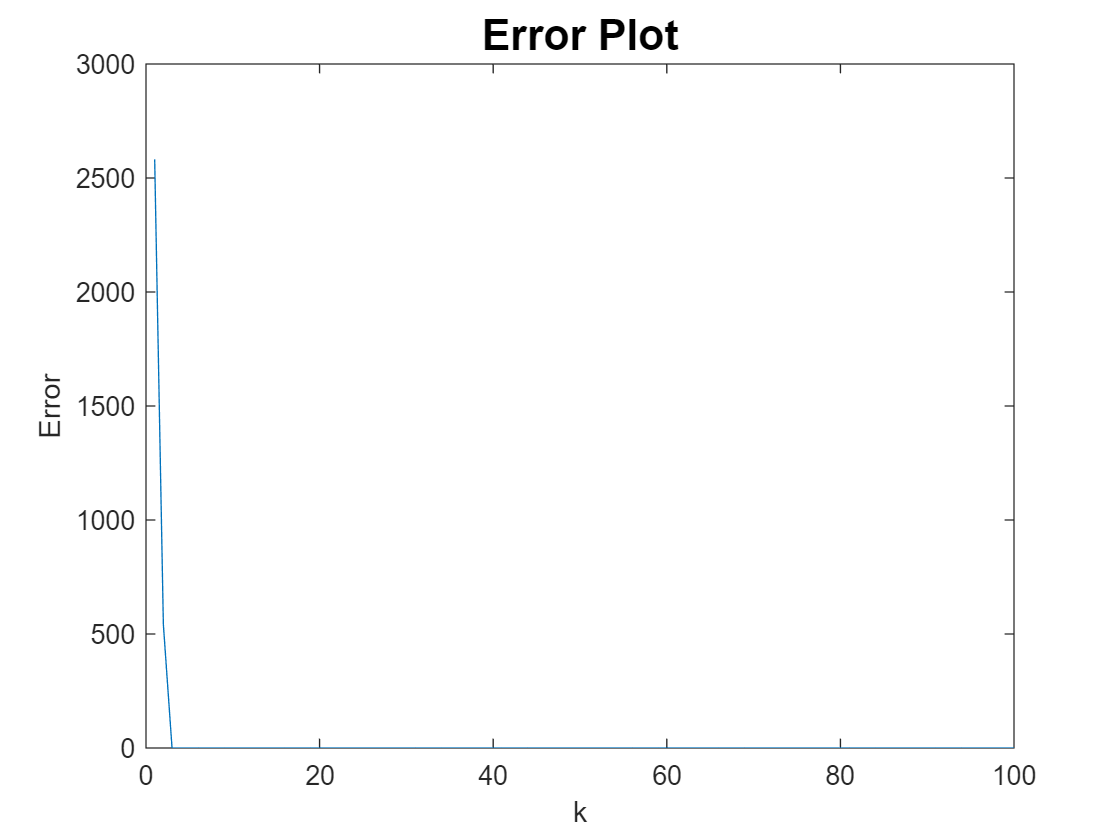

plot(1:big_k, err_fseq)
title('Error Plot','FontSize',16)
xlabel('k')
ylabel('Error')

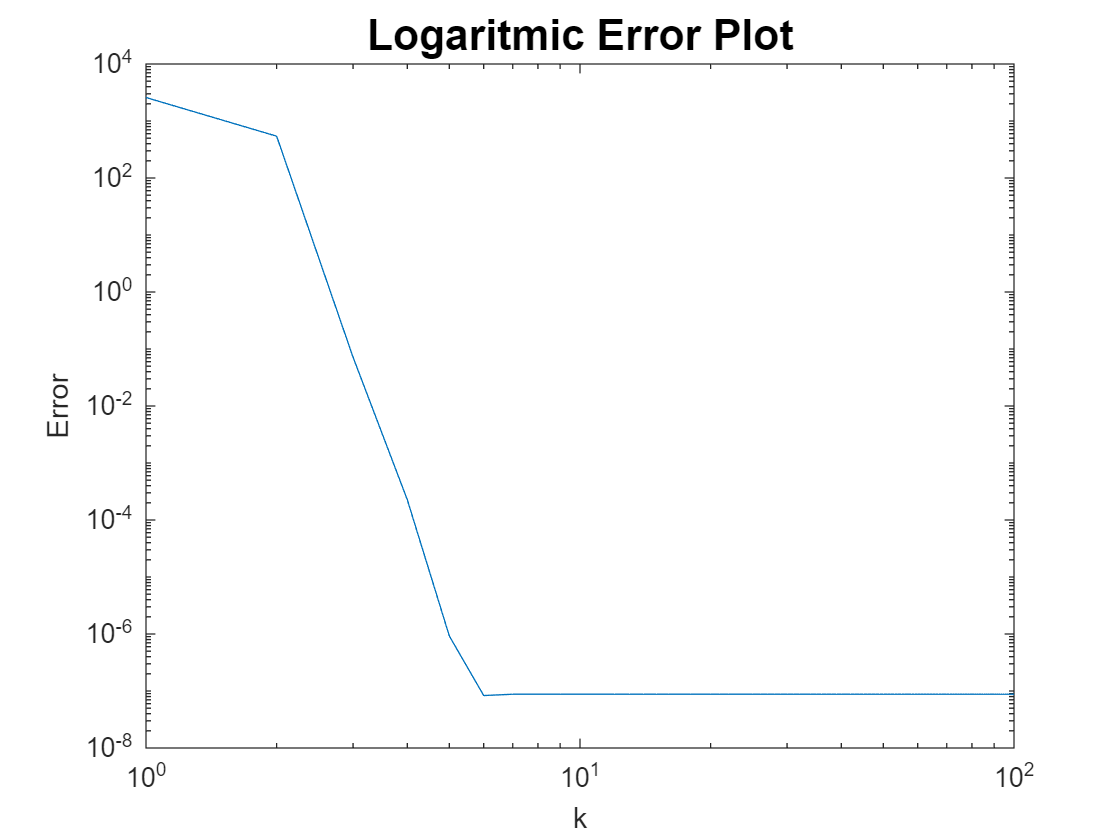

loglog(1:big_k, err_fseq)  % base-10 logarithmic scale on the x-axis and the y-axis
title('Logaritmic Error Plot','FontSize',16)
xlabel('k')
ylabel('Error')

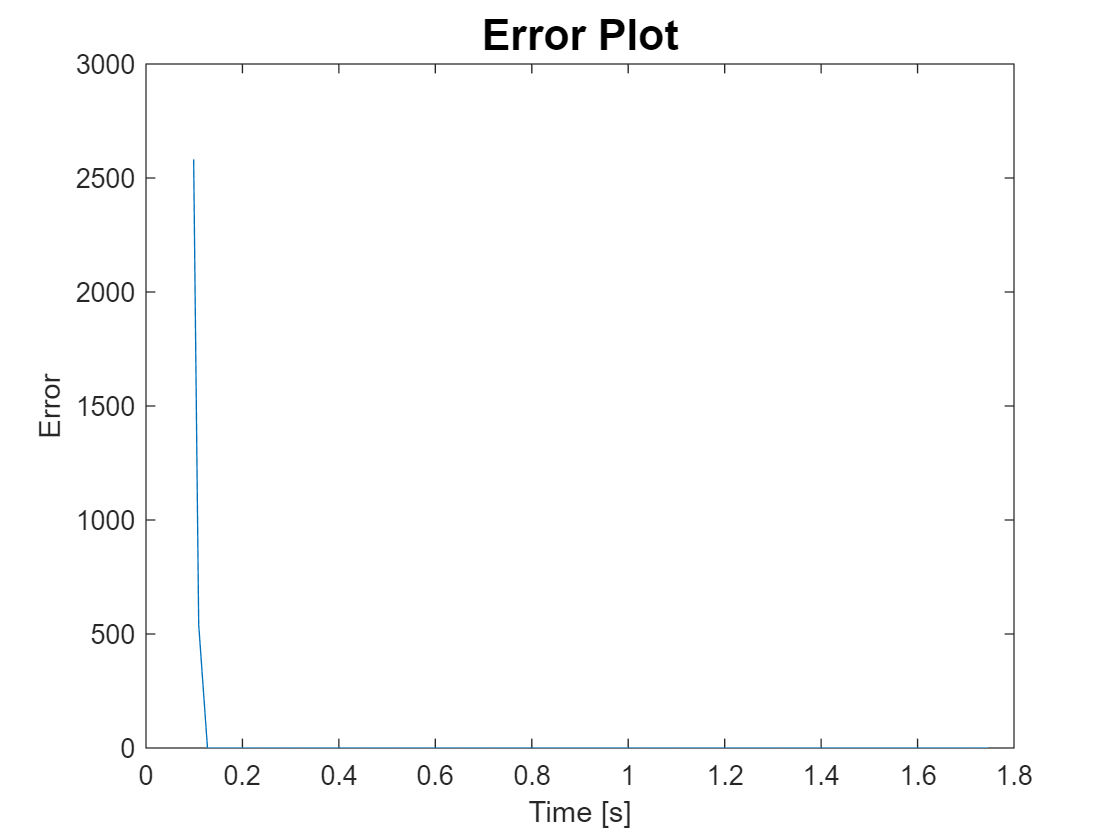

plot(timeCostseq, err_fseq)
title('Error Plot','FontSize',16)
xlabel('Time [s]')
ylabel('Error')

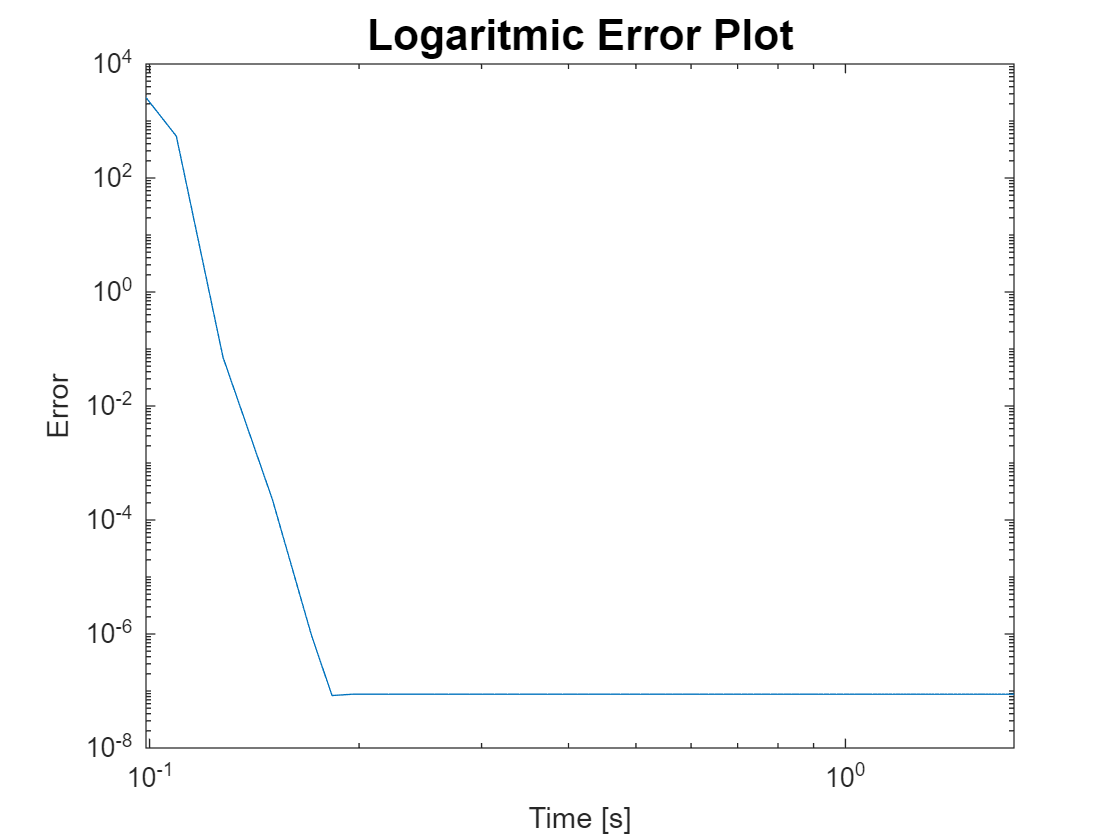

loglog(timeCostseq, err_fseq)  % base-10 logarithmic scale on the x-axis and the y-axis
title('Logaritmic Error Plot','FontSize',16)
xlabel('Time [s]')
ylabel('Error')

## Inexact Newton method - 10^3

### Parameters

kmax = 100;  % maximum number of iterations
step_k = 5;  % step between one iteration and the successive to memorize efficiently the orders fo convergence and the errors;
tolgrad = 1e-8;  % stopping criterion w.r.t. the norm of the gradient
c1 = 1e-4;  % factor of the Armijo condition
rho = 0.5;  % fixed factor used for reducing alpha0
btmax = 800;  % ﻿maximum number of steps for updating alpha
parameters = table(kmax, step_k, tolgrad, alpha0, c1, rho, btmax)

parameters = 1×7 table
    kmax    step_k    tolgrad    alpha0      c1      rho    btmax
    ____    ______    _______    ______    ______    ___    _____

    100       5        1e-08       10      0.0001    0.5     800 


% gradf = @(x) 0;
Hessf = @(x) 0;
FDgrad = 1;  % 'otherwise' case of "findiff_grad"
FDHess = 'Jc';
h = sqrt(eps);
fterms = fterms_lin;
pcg_maxit = 50;  % 100
[xk, fk, gradfk_norm, k, big_k, pk_itcount, err_fseq, ordconv_seq, totalTimeCost, timeCostseq] = ...
    innewton_bcktrck(x0, x_sol, f, gradf, Hessf, step_k, kmax, ...
    tolgrad, c1, rho, btmax, FDgrad, FDHess, h, fterms, pcg_maxit);

*** Tolerance is not respected ***

results_0 = table(xk, x_sol);
head(results_0, 8)

ans = 8×2 table
      xk      x_sol 
    ______    ______

         3         3
    3.1498    3.1498
         3         3
    3.1498    3.1498
         3         3
    3.1498    3.1498
         3         3
    3.1498    3.1498


tail(results_0, 8)

ans = 8×2 table
      xk      x_sol 
    ______    ______

         3         3
    3.1498    3.1498
         3         3
    3.1498    3.1498
         3         3
    3.1498    3.1498
         3         3
    3.1498    3.1498


gradfk_norm_x0 = norm(gradf(x0));
gradfk_norm_inf = norm(gradf(xk), "inf");
errf_final = err_fseq(end);
results_1 = table(fk, k, pk_itcount, gradfk_norm_x0, gradfk_norm, gradfk_norm_inf, errf_final, totalTimeCost)

results_1 = 1×8 table
      fk      k     pk_itcount    gradfk_norm_x0    gradfk_norm    gradfk_norm_inf    errf_final    totalTimeCost
    ______    __    __________    ______________    ___________    _______________    __________    _____________

    9.7895    29        36          9.7033e+10      8.3348e-14       1.1768e-14        0.064725       0.041392   


err_fseq = err_fseq';
ordconv_seq = ordconv_seq';
timeCostseq = timeCostseq';
results_2 = table(err_fseq, ordconv_seq, timeCostseq);
head(results_2, 8)

ans = 5×3 table
     err_fseq     ordconv_seq    timeCostseq
    __________    ___________    ___________

    1.6021e+08        2.7404      0.011359  
    1.1049e+06        2.7394      0.018584  
         34812        2.7188      0.024546  
         59.22         12047      0.033314  
      0.064725    2.4312e-11      0.041392  


tail(results_2, 8)

ans = 5×3 table
     err_fseq     ordconv_seq    timeCostseq
    __________    ___________    ___________

    1.6021e+08        2.7404      0.011359  
    1.1049e+06        2.7394      0.018584  
         34812        2.7188      0.024546  
         59.22         12047      0.033314  
      0.064725    2.4312e-11      0.041392  


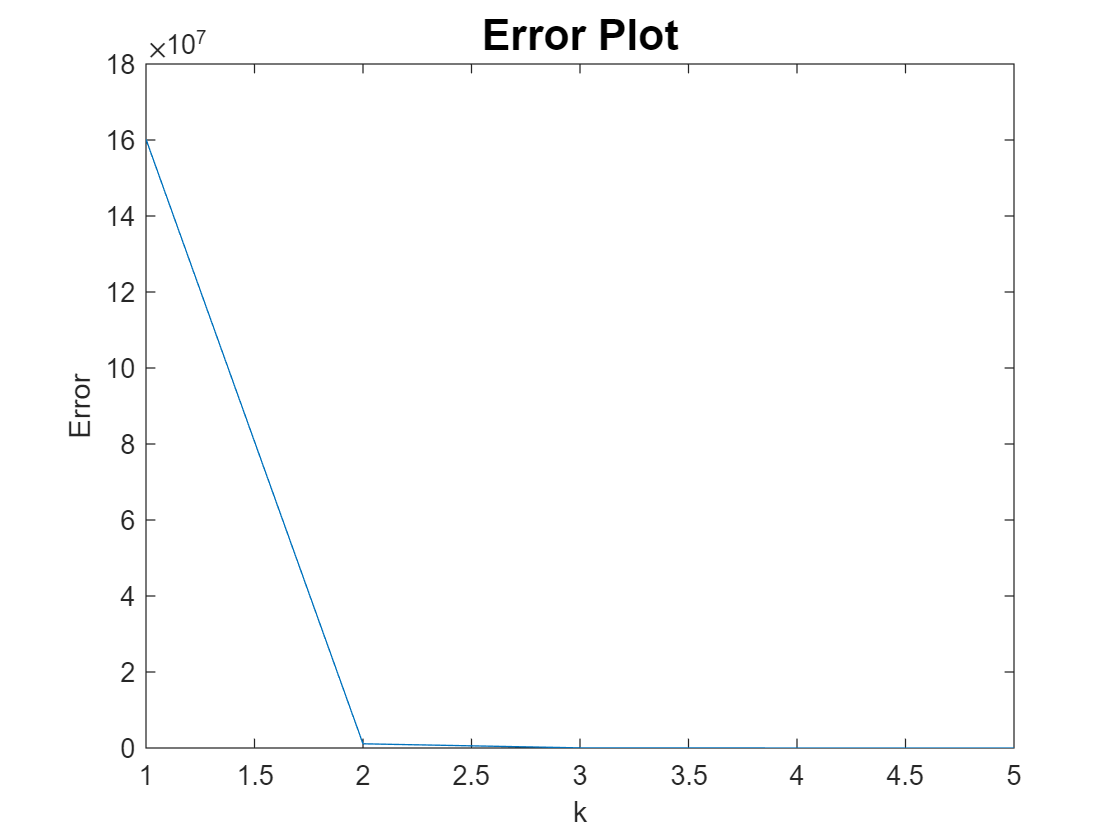

plot(1:big_k, err_fseq)
title('Error Plot','FontSize',16)
xlabel('k')
ylabel('Error')

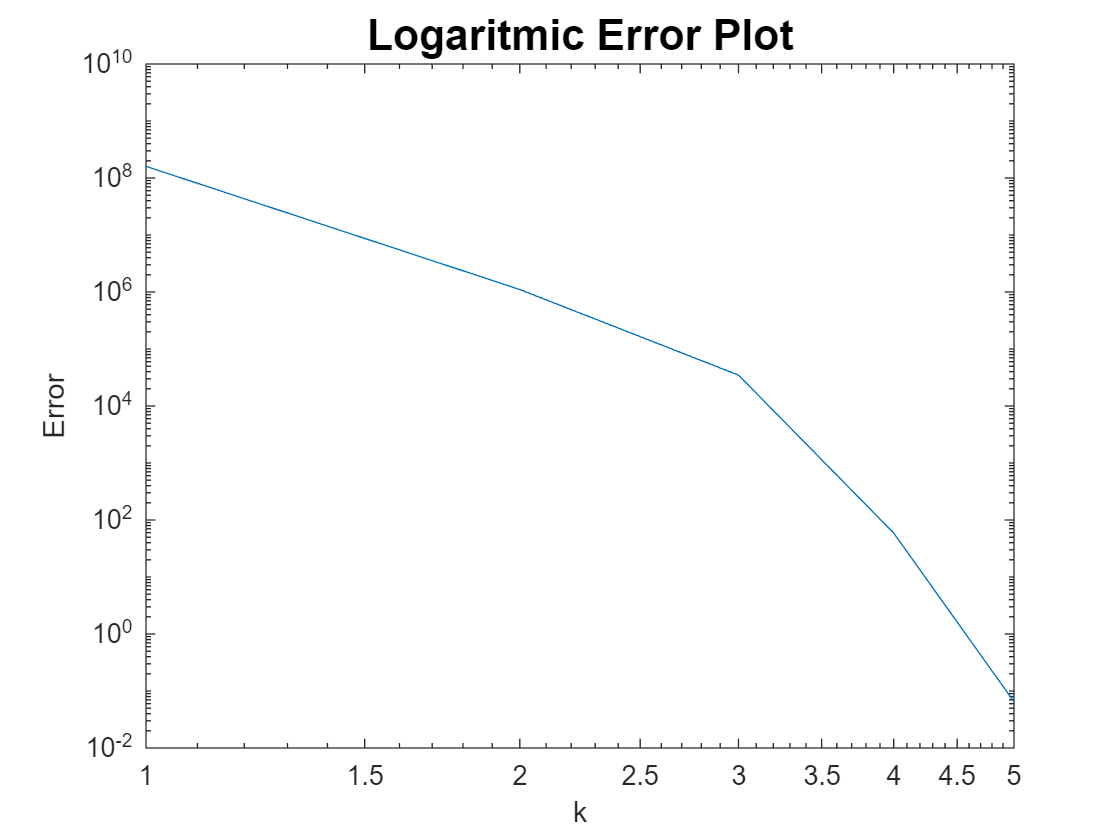

loglog(1:big_k, err_fseq)  % base-10 logarithmic scale on the x-axis and the y-axis
title('Logaritmic Error Plot','FontSize',16)
xlabel('k')
ylabel('Error')

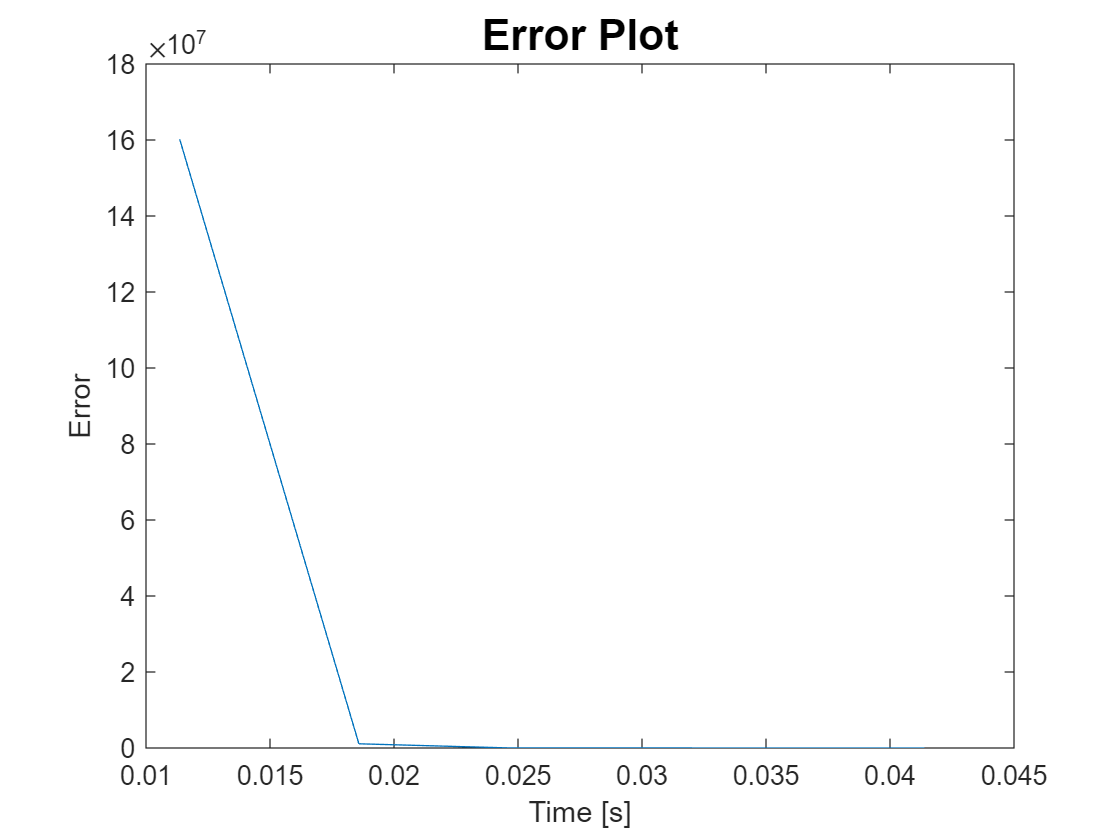

plot(timeCostseq, err_fseq)
title('Error Plot','FontSize',16)
xlabel('Time [s]')
ylabel('Error')

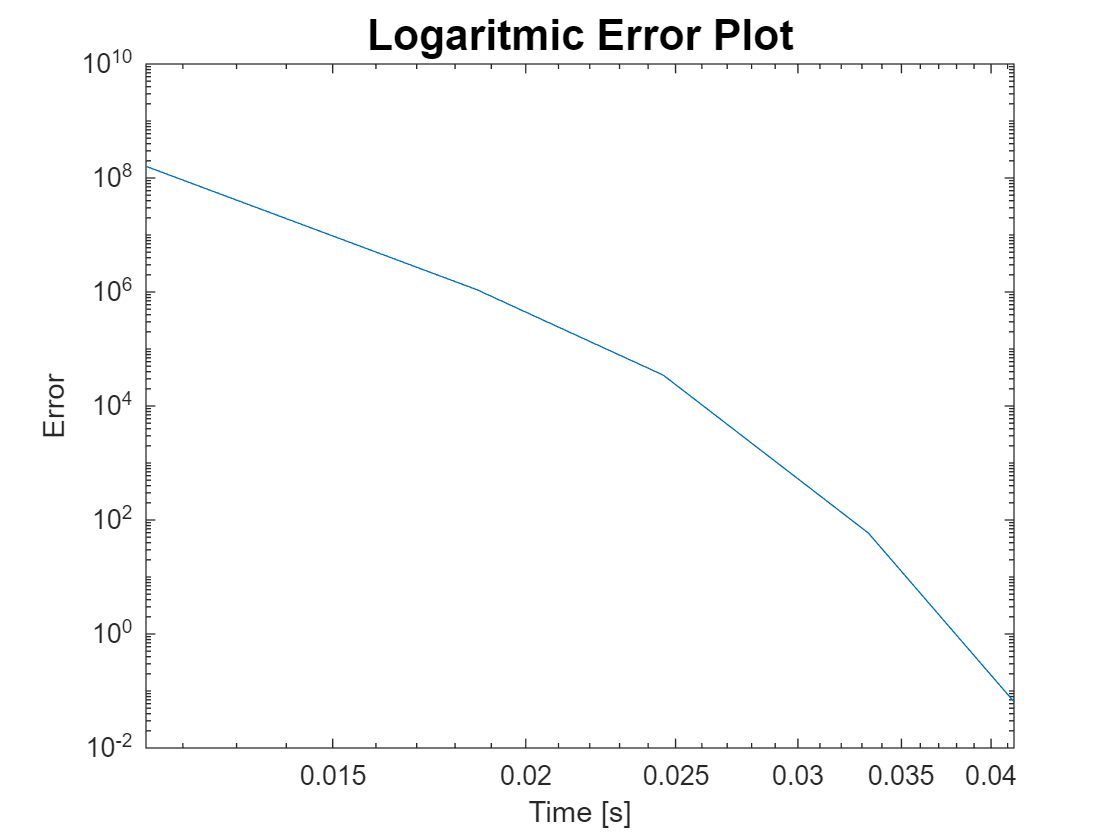

loglog(timeCostseq, err_fseq)  % base-10 logarithmic scale on the x-axis and the y-axis
title('Logaritmic Error Plot','FontSize',16)
xlabel('Time [s]')
ylabel('Error')

## Modified Newton method - 10^3

### Parameters

kmax = 100;  % maximum number of iterations
step_k = 5;  % step between one iteration and the successive to memorize efficiently the orders fo convergence and the errors;
tolgrad = 1e-8;  % stopping criterion w.r.t. the norm of the gradient
c1 = 1e-4;  % factor of the Armijo condition
rho = 0.1;  % fixed factor used for reducing alpha0
btmax = 800;  % ﻿maximum number of steps for updating alpha
parameters = table(kmax, step_k, tolgrad, alpha0, c1, rho, btmax)

parameters = 1×7 table
    kmax    step_k    tolgrad    alpha0      c1      rho    btmax
    ____    ______    _______    ______    ______    ___    _____

    100       5        1e-08       10      0.0001    0.1     800 


Hessf = @(x) 0;
FDgrad = 1;  % 'otherwise' case of "findiff_grad"
FDHess = 'Jc';
h = 0.001;  %sqrt(eps)*norm(x0);
[xk, fk, gradfk_norm, k, big_k, err_fseq, ordconv_seq, ...
    totalTimeCost, timeCostseq] = modnewton_bcktrck(x0,x_sol,f,gradf,...
    Hessf,step_k,kmax,tolgrad,c1,rho,btmax, FDgrad, FDHess, h);

*** Tolerance is not respected ***

results_0 = table(xk, x_sol);
head(results_0, 8)

ans = 8×2 table
      xk      x_sol 
    ______    ______

         3         3
    3.1498    3.1498
         3         3
    3.1498    3.1498
         3         3
    3.1498    3.1498
         3         3
    3.1498    3.1498


tail(results_0, 8)

ans = 8×2 table
      xk      x_sol 
    ______    ______

         3         3
    3.1498    3.1498
         3         3
    3.1498    3.1498
         3         3
    3.1498    3.1498
         3         3
    3.1498    3.1498


gradfk_norm_x0 = norm(gradf(x0));
gradfk_norm_inf = norm(gradf(xk), "inf");
errf_final = err_fseq(end);
results_1 = table(fk, k, gradfk_norm_x0, gradfk_norm, gradfk_norm_inf, errf_final, totalTimeCost)

results_1 = 1×7 table
      fk      k     gradfk_norm_x0    gradfk_norm    gradfk_norm_inf    errf_final    totalTimeCost
    ______    __    ______________    ___________    _______________    __________    _____________

    9.7895    47      9.7033e+10      4.7906e-12       4.8916e-13       8.7713e-08       0.24008   


err_fseq = err_fseq';
ordconv_seq = ordconv_seq';
timeCostseq = timeCostseq';
results_2 = table(err_fseq, ordconv_seq, timeCostseq);
head(results_2, 8)

ans = 8×3 table
     err_fseq     ordconv_seq    timeCostseq
    __________    ___________    ___________

    1.0019e+09      1.2416        0.037022  
    5.9659e+07      1.0251        0.060508  
    3.4979e+06      1.0399        0.085586  
    2.0525e+05      1.0488         0.10987  
         12025      1.0646         0.13144  
        691.99      1.0946         0.16134  
        33.412      1.1651          0.1867  
       0.34618      1.3486         0.21494  


tail(results_2, 8)

ans = 8×3 table
     err_fseq     ordconv_seq    timeCostseq
    __________    ___________    ___________

    5.9659e+07       1.0251       0.060508  
    3.4979e+06       1.0399       0.085586  
    2.0525e+05       1.0488        0.10987  
         12025       1.0646        0.13144  
        691.99       1.0946        0.16134  
        33.412       1.1651         0.1867  
       0.34618       1.3486        0.21494  
    8.7713e-08      0.51286        0.24008  


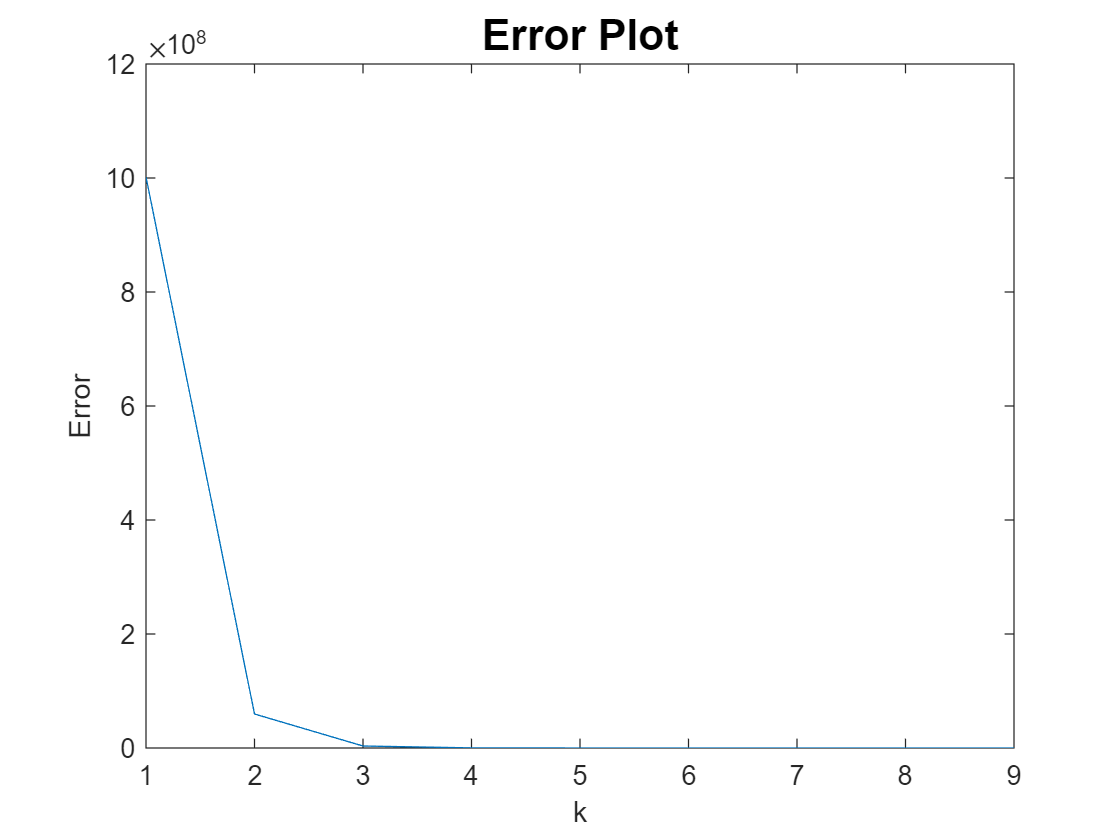

plot(1:big_k, err_fseq)
title('Error Plot','FontSize',16)
xlabel('k')
ylabel('Error')

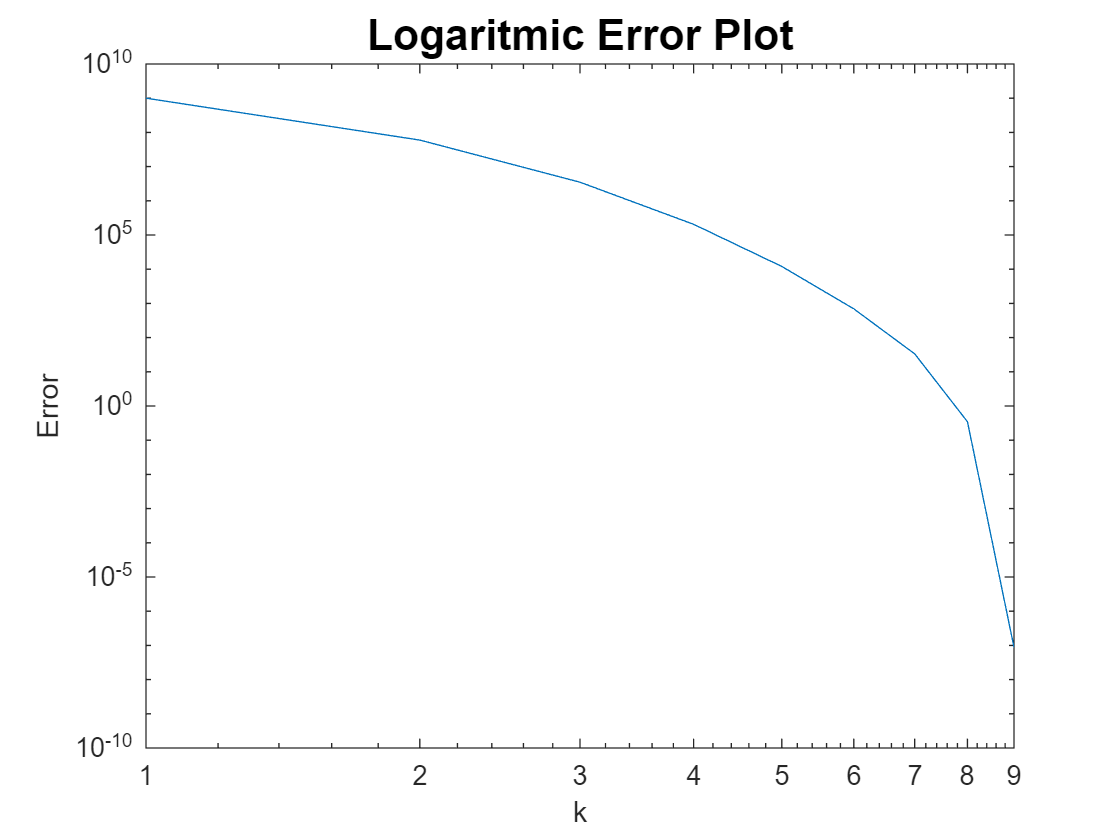

loglog(1:big_k, err_fseq)  % base-10 logarithmic scale on the x-axis and the y-axis
title('Logaritmic Error Plot','FontSize',16)
xlabel('k')
ylabel('Error')

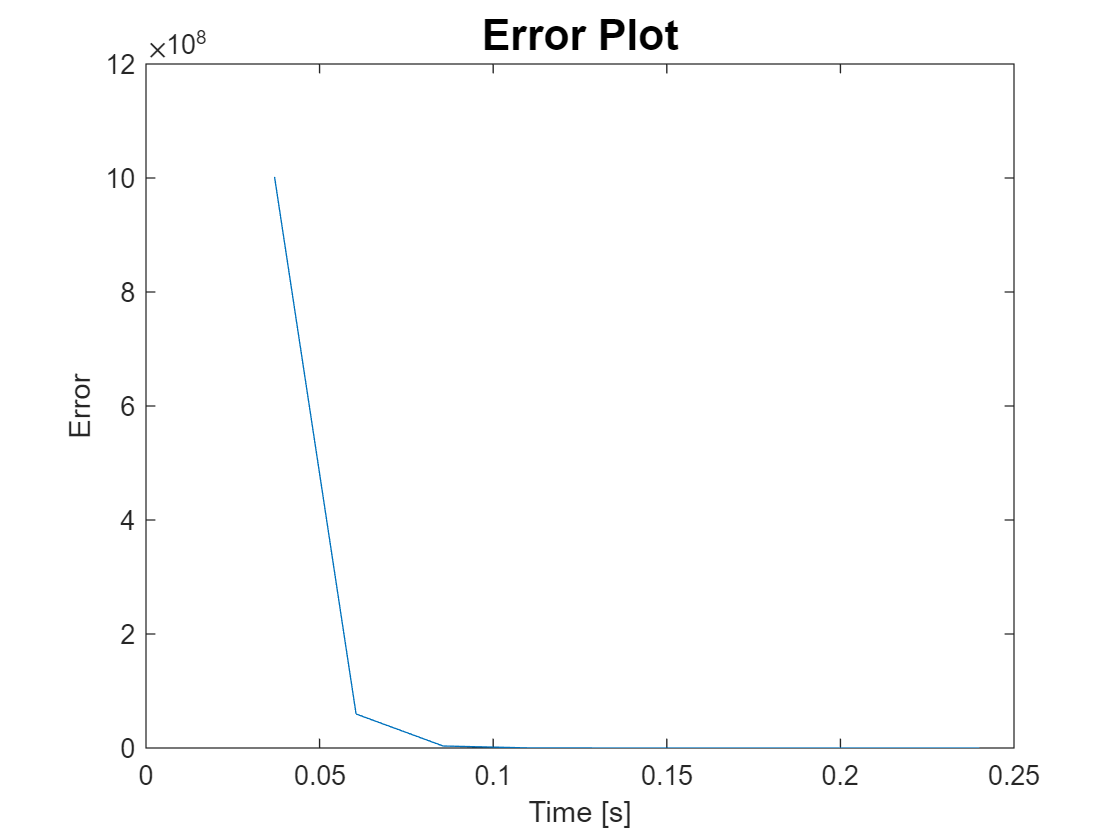

plot(timeCostseq, err_fseq)
title('Error Plot','FontSize',16)
xlabel('Time [s]')
ylabel('Error')

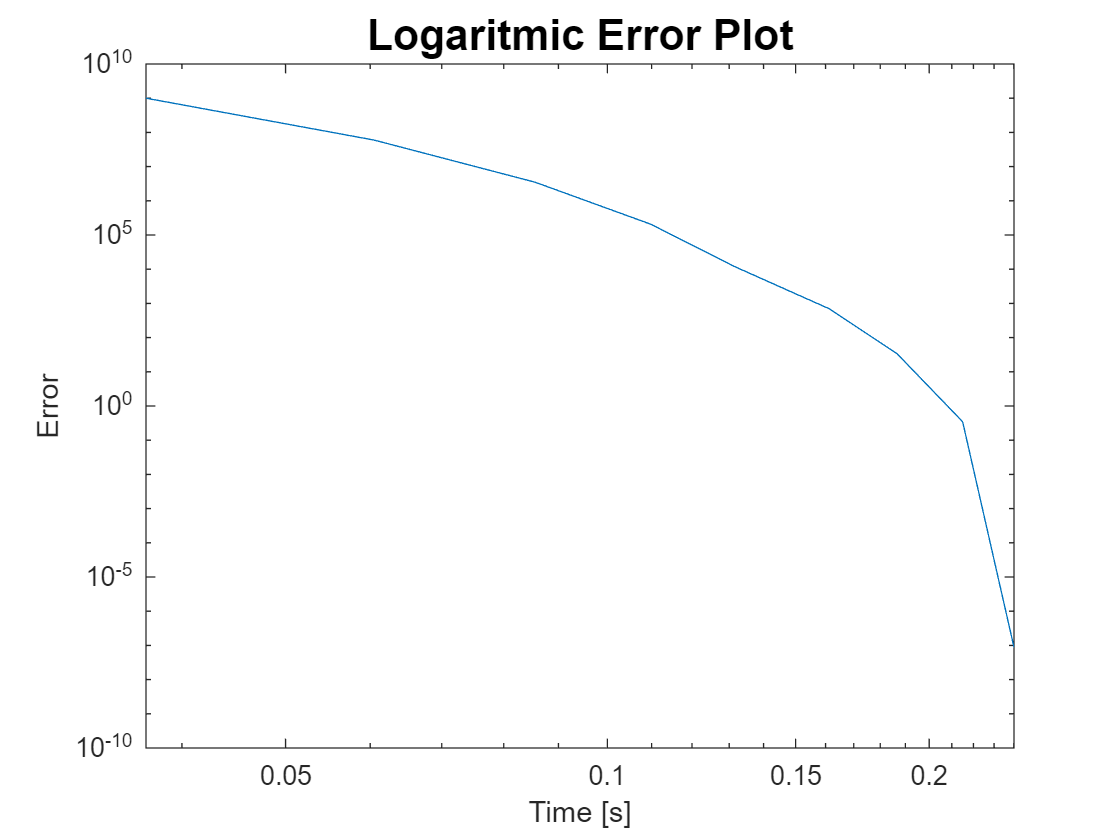

loglog(timeCostseq, err_fseq)  % base-10 logarithmic scale on the x-axis and the y-axis
title('Logaritmic Error Plot','FontSize',16)
xlabel('Time [s]')
ylabel('Error')

## Test function: Generalization of the Brown function 1 - 10^4

% Dimension n (multiple of 2)
n = 10^4;  % 10^4;

% Initializations
f = @(x) 0;
f_plus = @(x) 0;
x0 = zeros(n, 1);

% Generalization of the Brown function 1
for j = 1 : (n - 2)/2
    f_1 = @(x) ((((x(2*j-1, :)) - 3).^2)/1000 - ...
        (x(2*j-1, :) - x(2*j, :)) + ...
        exp(20*(x(2*j-1, :) - x(2*j, :))));  % Brown function 1 (j=1)
    f_2 = @(x) (x(2*j-1, :) - 3);
    f_plus = @(x) f_plus(x) + f_2(x);
    f = @(x) f(x) + f_1(x);  % Generalization of the Brown function 1
end

% Starting point x0
for j = 1 : n
    if mod(j, 2) == 0
        x0(j) = -1;
    else
        x0(j) = 0;
    end
end
f = @(x) f(x) + (f_plus(x))^2;

% Expected solution
x_sol = ones(1, n)' .* 3;
for i = 1 : n
    if mod(i, 2) == 0
        x_sol(i) = 3.1498;  % arrotondato per eccesso
    end
end

% Gradient
gradf = @(x) generalized_brown_grad(x);

### Parameters 

load('forcing_terms.mat')

kmax = 1000;  % maximum number of iterations
step_k = 10;  % step between one iteration and the successive to memorize efficiently the orders fo convergence and the errors;
tolgrad = 1e-8;  % stopping criterion w.r.t. the norm of the gradient
alpha0 = 10;  % initial step-length
c1 = 1e-4;  % factor of the Armijo condition
rho = 0.1;  % fixed factor used for reducing alpha0
btmax = 800;  % ﻿maximum number of steps for updating alpha
parameters = table(kmax, step_k, tolgrad, alpha0, c1, rho, btmax)

parameters = 1×7 table
    kmax    step_k    tolgrad    alpha0      c1      rho    btmax
    ____    ______    _______    ______    ______    ___    _____

    1000      10       1e-08       10      0.0001    0.1     800 


## Steepest descent method - 10^4

[xk, fk, gradfk_norm, k, big_k, err_fseq, ordconv_seq, totalTimeCost, timeCostseq] = ...
    steepest_desc_bckt(x0, x_sol, f, gradf, alpha0, step_k, kmax, tolgrad, c1, rho, btmax);

*** Iterations overcome maximum number of iterations ***

results_0 = table(xk, x_sol);
head(results_0, 8)

ans = 8×2 table
      xk      x_sol 
    ______    ______

         3         3
    3.1498    3.1498
         3         3
    3.1498    3.1498
         3         3
    3.1498    3.1498
         3         3
    3.1498    3.1498


tail(results_0, 8)

ans = 8×2 table
      xk      x_sol 
    ______    ______

         3         3
    3.1498    3.1498
         3         3
    3.1498    3.1498
         3         3
    3.1498    3.1498
         3         3
    3.1498    3.1498


gradfk_norm_x0 = norm(gradf(x0));
gradfk_norm_inf = norm(gradf(xk), "inf");
errf_final = err_fseq(end);
results_1 = table(fk, k, gradfk_norm_x0, gradfk_norm, gradfk_norm_inf, errf_final, totalTimeCost)

results_1 = 1×7 table
      fk       k      gradfk_norm_x0    gradfk_norm    gradfk_norm_inf    errf_final    totalTimeCost
    ______    ____    ______________    ___________    _______________    __________    _____________

    9.7895    1000      9.7033e+10       3.179e-08       4.4147e-09       8.7797e-08       1.8071    


err_fseq = err_fseq';
ordconv_seq = ordconv_seq';
timeCostseq = timeCostseq';
results_2 = table(err_fseq, ordconv_seq, timeCostseq);
head(results_2, 8)

ans = 8×3 table
     err_fseq     ordconv_seq    timeCostseq
    __________    ___________    ___________

        2581.7       634.05       0.084108  
        541.68      0.12954       0.092866  
      0.071669      0.82051        0.11394  
    0.00022706       2.6005        0.13545  
    9.1987e-07       6.3186        0.15279  
    8.3217e-08       12.962        0.16866  
    8.7777e-08       8.6175        0.18863  
    8.7797e-08       16.233        0.20541  


tail(results_2, 8)

ans = 8×3 table
     err_fseq     ordconv_seq    timeCostseq
    __________    ___________    ___________

    8.7797e-08      0.12475        1.6956   
    8.7797e-08     -0.74422        1.7106   
    8.7797e-08      -3.0463         1.723   
    8.7797e-08      0.12475        1.7405   
    8.7797e-08     -0.74422        1.7563   
    8.7797e-08      -3.0463        1.7714   
    8.7797e-08      -3.0462        1.7892   
    8.7797e-08     -0.74422        1.8071   


plot(1:big_k, err_fseq)
title('Error Plot','FontSize',16)
xlabel('k')
ylabel('Error')

loglog(1:big_k, err_fseq)  % base-10 logarithmic scale on the x-axis and the y-axis
title('Logaritmic Error Plot','FontSize',16)
xlabel('k')
ylabel('Error')

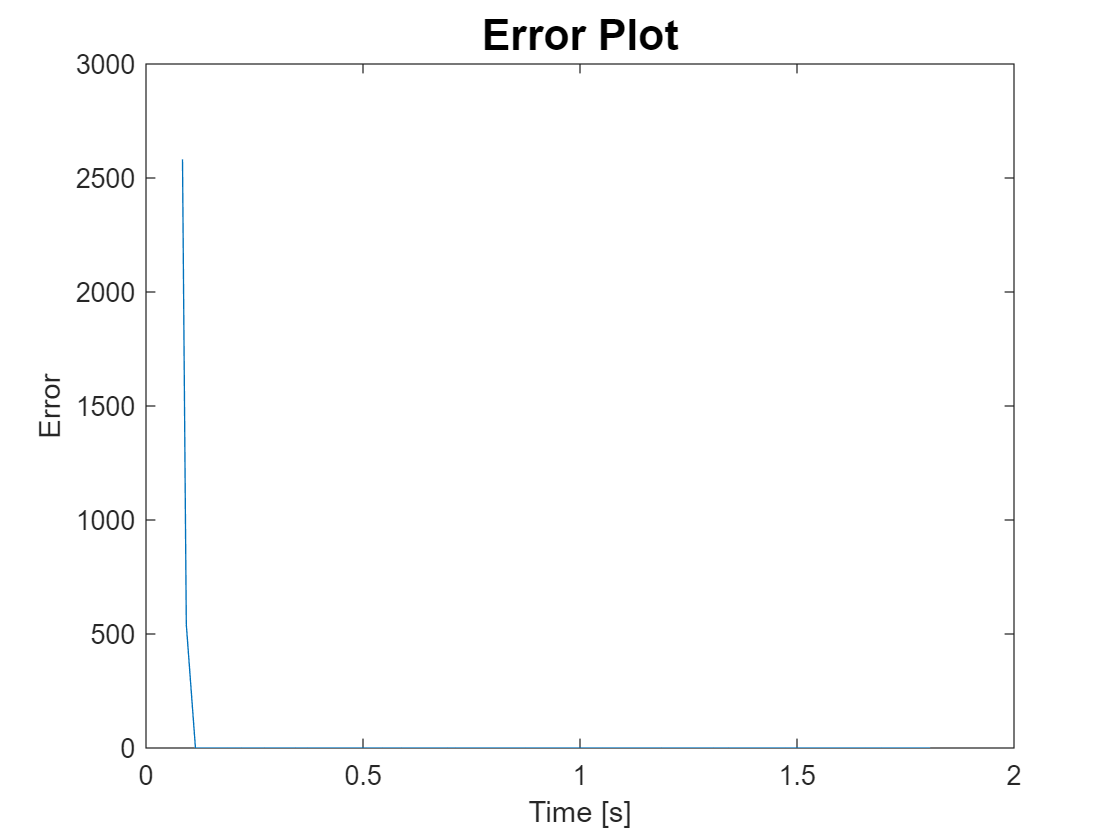

plot(timeCostseq, err_fseq)
title('Error Plot','FontSize',16)
xlabel('Time [s]')
ylabel('Error')

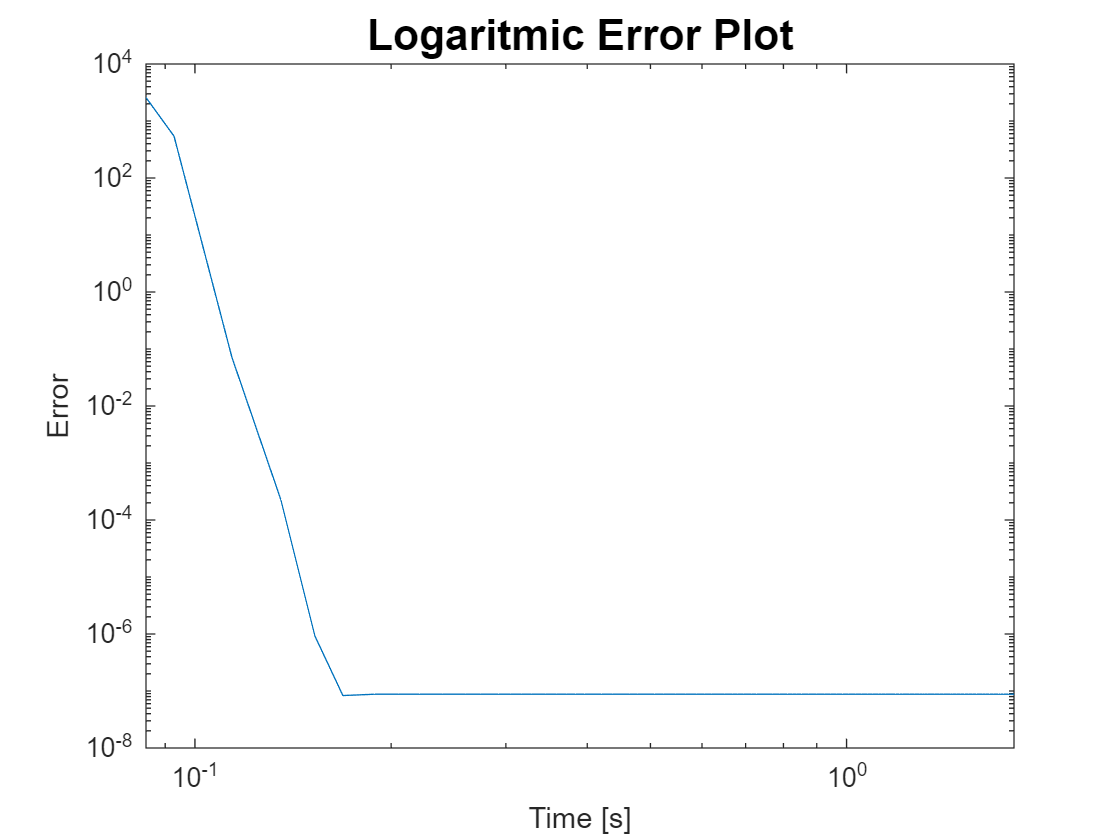

loglog(timeCostseq, err_fseq)  % base-10 logarithmic scale on the x-axis and the y-axis
title('Logaritmic Error Plot','FontSize',16)
xlabel('Time [s]')
ylabel('Error')

## Inexact Newton method - 10^4

### Parameters

kmax = 100;  % maximum number of iterations
step_k = 5;  % step between one iteration and the successive to memorize efficiently the orders fo convergence and the errors;
tolgrad = 1e-8;  % stopping criterion w.r.t. the norm of the gradient
c1 = 1e-4;  % factor of the Armijo condition
rho = 0.5;  % fixed factor used for reducing alpha0
btmax = 800;  % ﻿maximum number of steps for updating alpha
parameters = table(kmax, step_k, tolgrad, alpha0, c1, rho, btmax)

parameters = 1×7 table
    kmax    step_k    tolgrad    alpha0      c1      rho    btmax
    ____    ______    _______    ______    ______    ___    _____

    100       5        1e-08       10      0.0001    0.5     800 


% gradf = @(x) 0;
Hessf = @(x) 0;
FDgrad = 1;  % 'otherwise' case of "findiff_grad"
FDHess = 'Jc';
h = sqrt(eps);
fterms = fterms_lin;
pcg_maxit = 50;  % 100
[xk, fk, gradfk_norm, k, big_k, pk_itcount, err_fseq, ordconv_seq, totalTimeCost, timeCostseq] = ...
    innewton_bcktrck(x0, x_sol, f, gradf, Hessf, step_k, kmax, ...
    tolgrad, c1, rho, btmax, FDgrad, FDHess, h, fterms, pcg_maxit);

*** Tolerance is not respected ***

results_0 = table(xk, x_sol);
head(results_0, 8)

ans = 8×2 table
      xk      x_sol 
    ______    ______

         3         3
    3.1498    3.1498
         3         3
    3.1498    3.1498
         3         3
    3.1498    3.1498
         3         3
    3.1498    3.1498


tail(results_0, 8)

ans = 8×2 table
      xk      x_sol 
    ______    ______

         3         3
    3.1498    3.1498
         3         3
    3.1498    3.1498
         3         3
    3.1498    3.1498
         3         3
    3.1498    3.1498


gradfk_norm_x0 = norm(gradf(x0));
gradfk_norm_inf = norm(gradf(xk), "inf");
errf_final = err_fseq(end);
results_1 = table(fk, k, pk_itcount, gradfk_norm_x0, gradfk_norm, gradfk_norm_inf, errf_final, totalTimeCost)

results_1 = 1×8 table
      fk      k     pk_itcount    gradfk_norm_x0    gradfk_norm    gradfk_norm_inf    errf_final    totalTimeCost
    ______    __    __________    ______________    ___________    _______________    __________    _____________

    9.7895    29        36          9.7033e+10      8.3348e-14       1.1768e-14        0.064725       0.030694   


err_fseq = err_fseq';
ordconv_seq = ordconv_seq';
timeCostseq = timeCostseq';
results_2 = table(err_fseq, ordconv_seq, timeCostseq);
head(results_2, 8)

ans = 5×3 table
     err_fseq     ordconv_seq    timeCostseq
    __________    ___________    ___________

    1.6021e+08        2.7404      0.0075963 
    1.1049e+06        2.7394        0.01359 
         34812        2.7188       0.019424 
         59.22         12047       0.025128 
      0.064725    2.4312e-11       0.030694 


tail(results_2, 8)

ans = 5×3 table
     err_fseq     ordconv_seq    timeCostseq
    __________    ___________    ___________

    1.6021e+08        2.7404      0.0075963 
    1.1049e+06        2.7394        0.01359 
         34812        2.7188       0.019424 
         59.22         12047       0.025128 
      0.064725    2.4312e-11       0.030694 


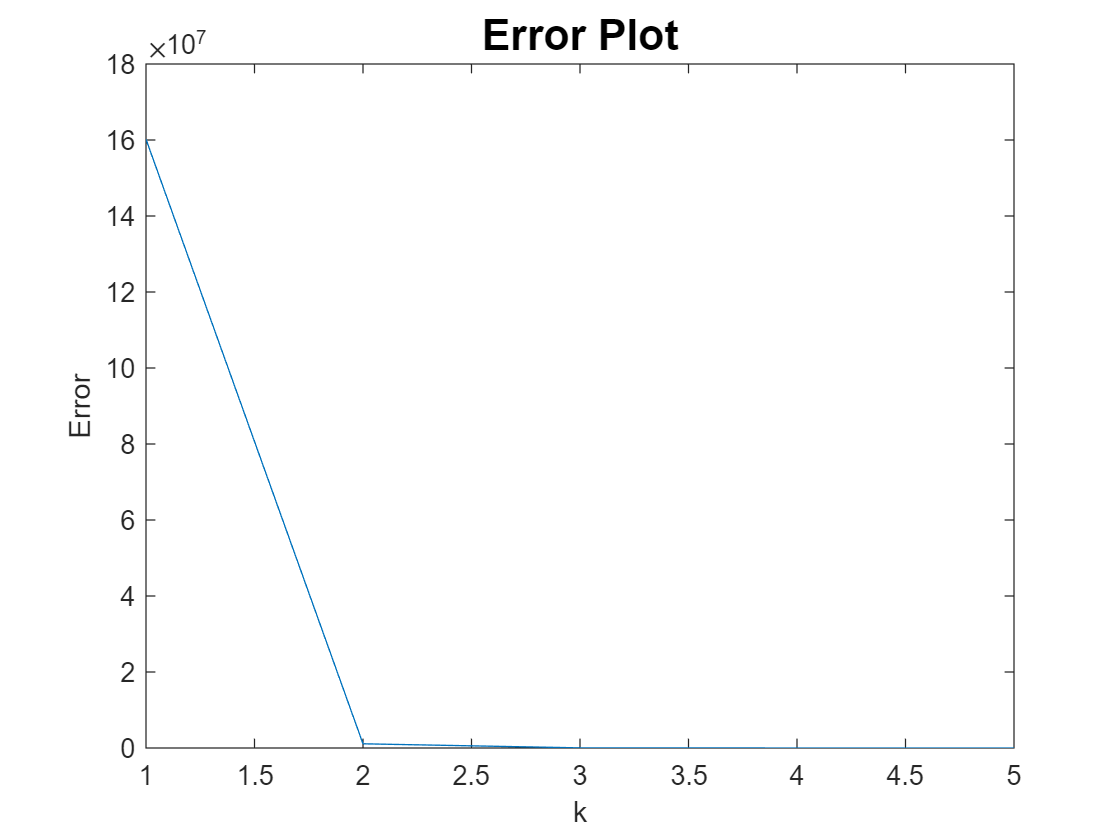

plot(1:big_k, err_fseq)
title('Error Plot','FontSize',16)
xlabel('k')
ylabel('Error')

loglog(1:big_k, err_fseq)  % base-10 logarithmic scale on the x-axis and the y-axis
title('Logaritmic Error Plot','FontSize',16)
xlabel('k')
ylabel('Error')

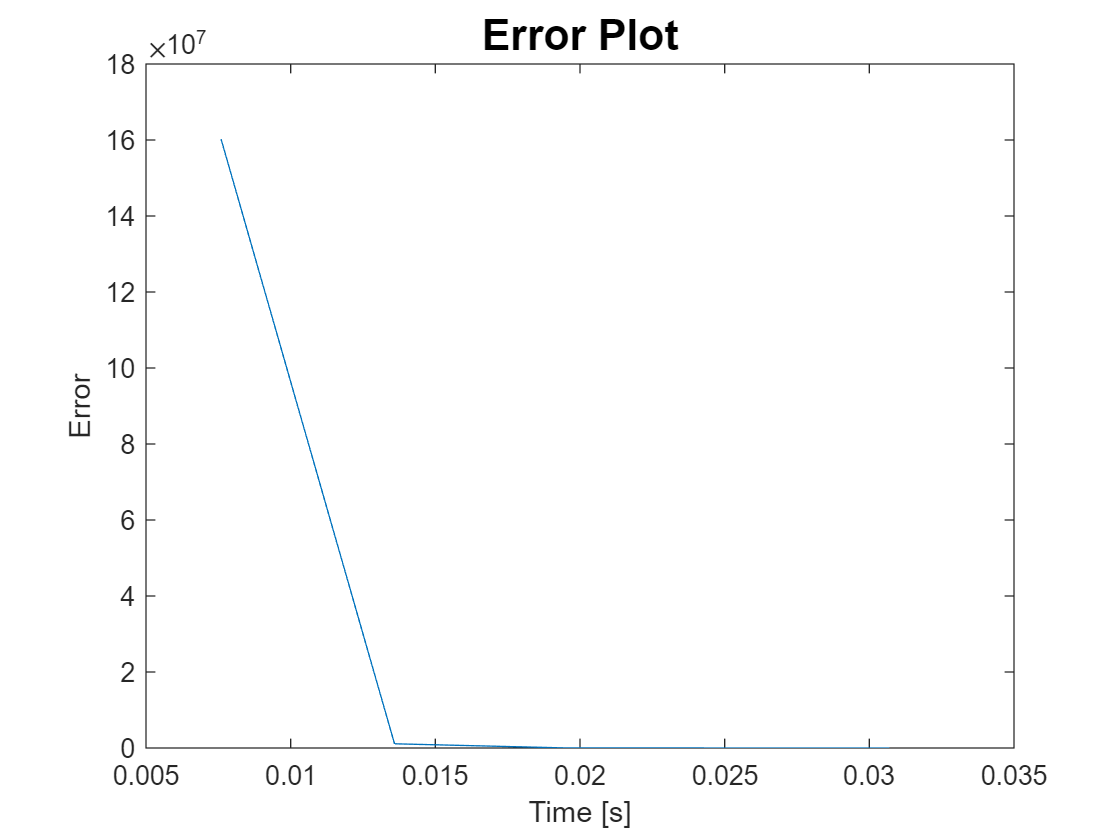

plot(timeCostseq, err_fseq)
title('Error Plot','FontSize',16)
xlabel('Time [s]')
ylabel('Error')

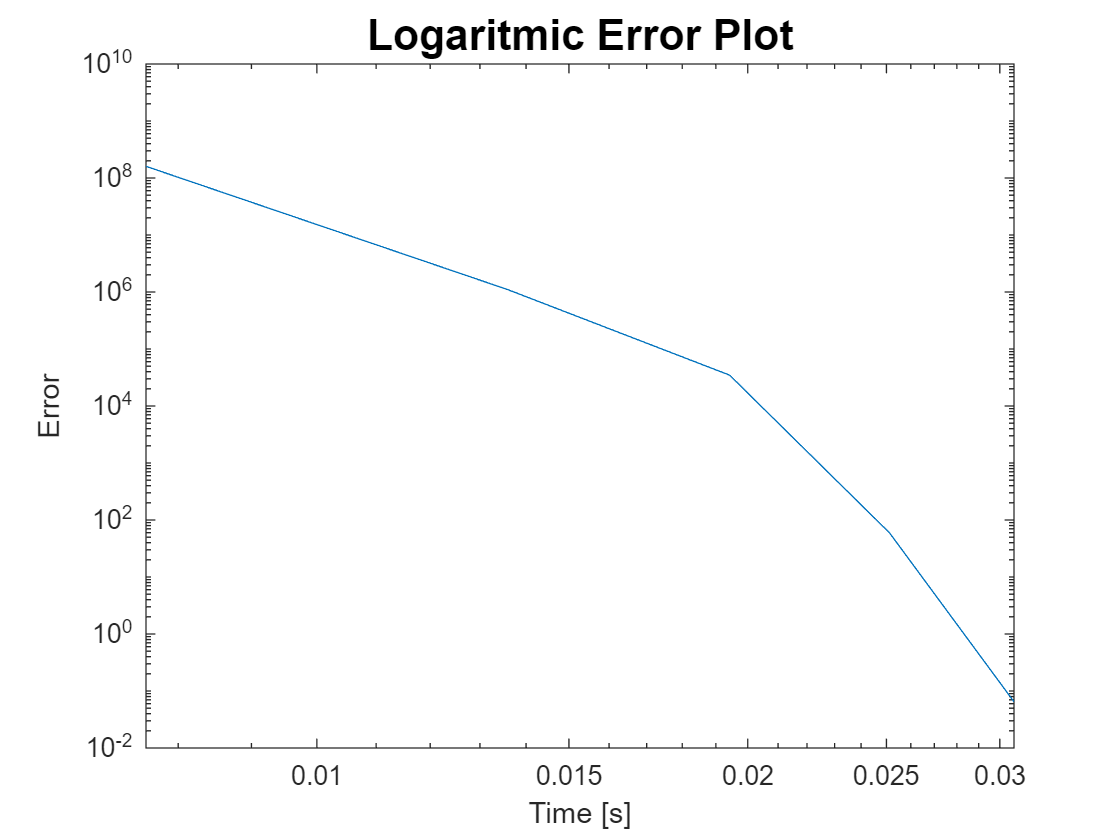

loglog(timeCostseq, err_fseq)  % base-10 logarithmic scale on the x-axis and the y-axis
title('Logaritmic Error Plot','FontSize',16)
xlabel('Time [s]')
ylabel('Error')

## Modified Newton method - 10^4

### Parameters

kmax = 100;  % maximum number of iterations
step_k = 5;  % step between one iteration and the successive to memorize efficiently the orders fo convergence and the errors;
tolgrad = 1e-8;  % stopping criterion w.r.t. the norm of the gradient
c1 = 1e-4;  % factor of the Armijo condition
rho = 0.1;  % fixed factor used for reducing alpha0
btmax = 800;  % ﻿maximum number of steps for updating alpha
parameters = table(kmax, step_k, tolgrad, alpha0, c1, rho, btmax)

parameters = 1×7 table
    kmax    step_k    tolgrad    alpha0      c1      rho    btmax
    ____    ______    _______    ______    ______    ___    _____

    100       5        1e-08       10      0.0001    0.1     800 


Hessf = @(x) 0;
FDgrad = 1;  % 'otherwise' case of "findiff_grad"
FDHess = 'Jc';
h = 0.001;  %sqrt(eps)*norm(x0);
[xk, fk, gradfk_norm, k, big_k, err_fseq, ordconv_seq, ...
    totalTimeCost, timeCostseq] = modnewton_bcktrck(x0,x_sol,f,gradf,...
    Hessf,step_k,kmax,tolgrad,c1,rho,btmax, FDgrad, FDHess, h);

*** Tolerance is not respected ***

results_0 = table(xk, x_sol);
head(results_0, 8)

ans = 8×2 table
      xk      x_sol 
    ______    ______

         3         3
    3.1498    3.1498
         3         3
    3.1498    3.1498
         3         3
    3.1498    3.1498
         3         3
    3.1498    3.1498


tail(results_0, 8)

ans = 8×2 table
      xk      x_sol 
    ______    ______

         3         3
    3.1498    3.1498
         3         3
    3.1498    3.1498
         3         3
    3.1498    3.1498
         3         3
    3.1498    3.1498


gradfk_norm_x0 = norm(gradf(x0));
gradfk_norm_inf = norm(gradf(xk), "inf");
errf_final = err_fseq(end);
results_1 = table(fk, k, gradfk_norm_x0, gradfk_norm, gradfk_norm_inf, errf_final, totalTimeCost)

results_1 = 1×7 table
      fk      k     gradfk_norm_x0    gradfk_norm    gradfk_norm_inf    errf_final    totalTimeCost
    ______    __    ______________    ___________    _______________    __________    _____________

    9.7895    47      9.7033e+10      4.7906e-12       4.8916e-13       8.7713e-08       0.22435   


err_fseq = err_fseq';
ordconv_seq = ordconv_seq';
timeCostseq = timeCostseq';
results_2 = table(err_fseq, ordconv_seq, timeCostseq);
head(results_2, 8)

ans = 8×3 table
     err_fseq     ordconv_seq    timeCostseq
    __________    ___________    ___________

    1.0019e+09      1.2416        0.035531  
    5.9659e+07      1.0251        0.058904  
    3.4979e+06      1.0399        0.087354  
    2.0525e+05      1.0488         0.10963  
         12025      1.0646         0.13086  
        691.99      1.0946         0.15526  
        33.412      1.1651         0.17626  
       0.34618      1.3486         0.19993  


tail(results_2, 8)

ans = 8×3 table
     err_fseq     ordconv_seq    timeCostseq
    __________    ___________    ___________

    5.9659e+07       1.0251       0.058904  
    3.4979e+06       1.0399       0.087354  
    2.0525e+05       1.0488        0.10963  
         12025       1.0646        0.13086  
        691.99       1.0946        0.15526  
        33.412       1.1651        0.17626  
       0.34618       1.3486        0.19993  
    8.7713e-08      0.51286        0.22435  


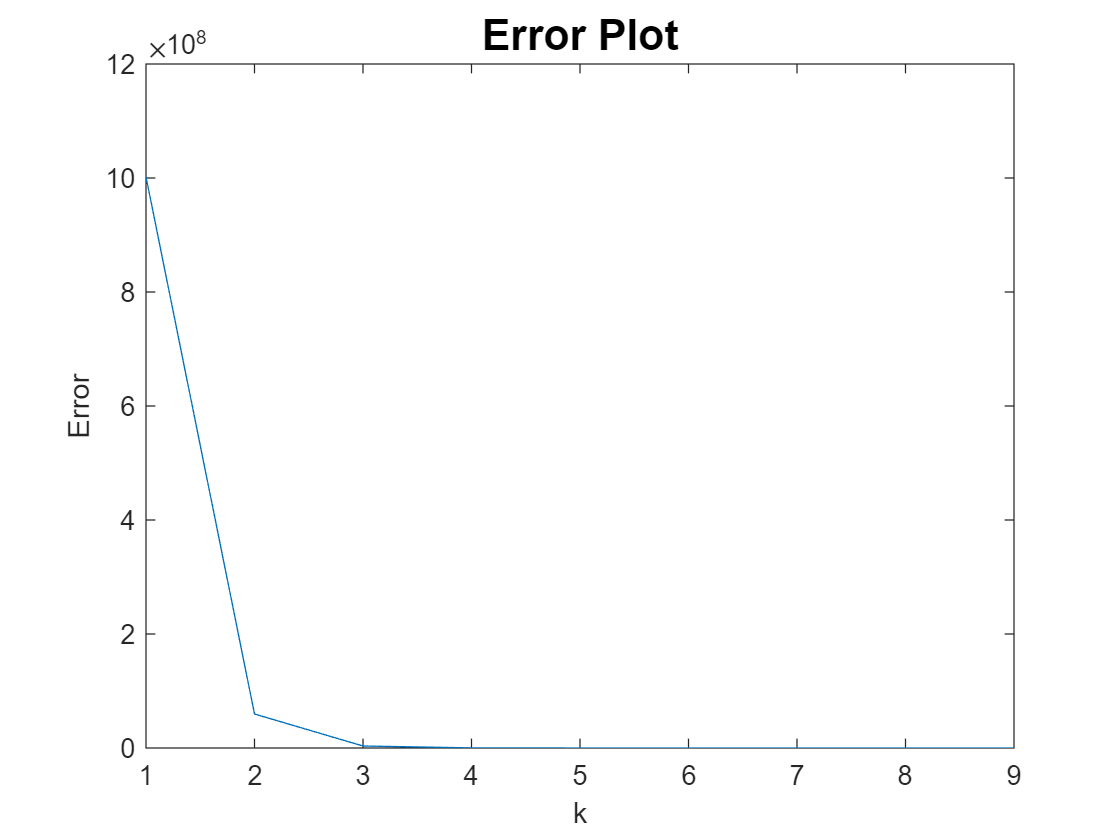

plot(1:big_k, err_fseq)
title('Error Plot','FontSize',16)
xlabel('k')
ylabel('Error')

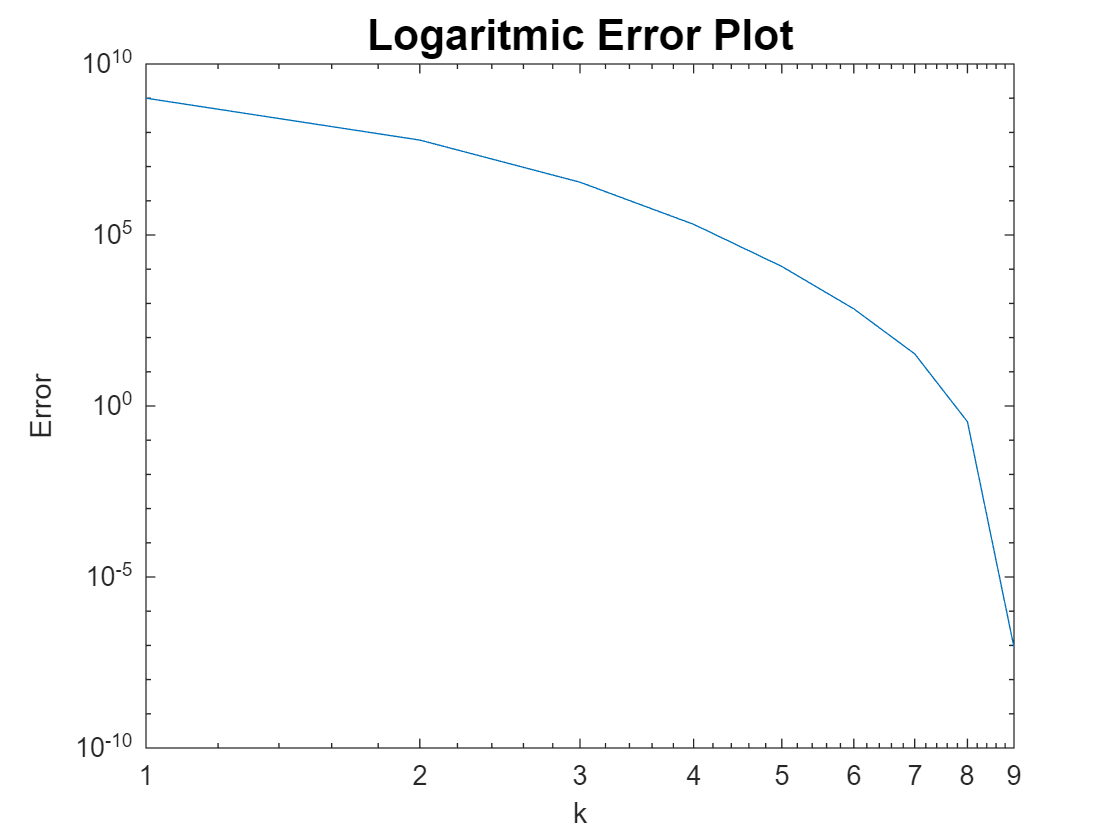

loglog(1:big_k, err_fseq)  % base-10 logarithmic scale on the x-axis and the y-axis
title('Logaritmic Error Plot','FontSize',16)
xlabel('k')
ylabel('Error')

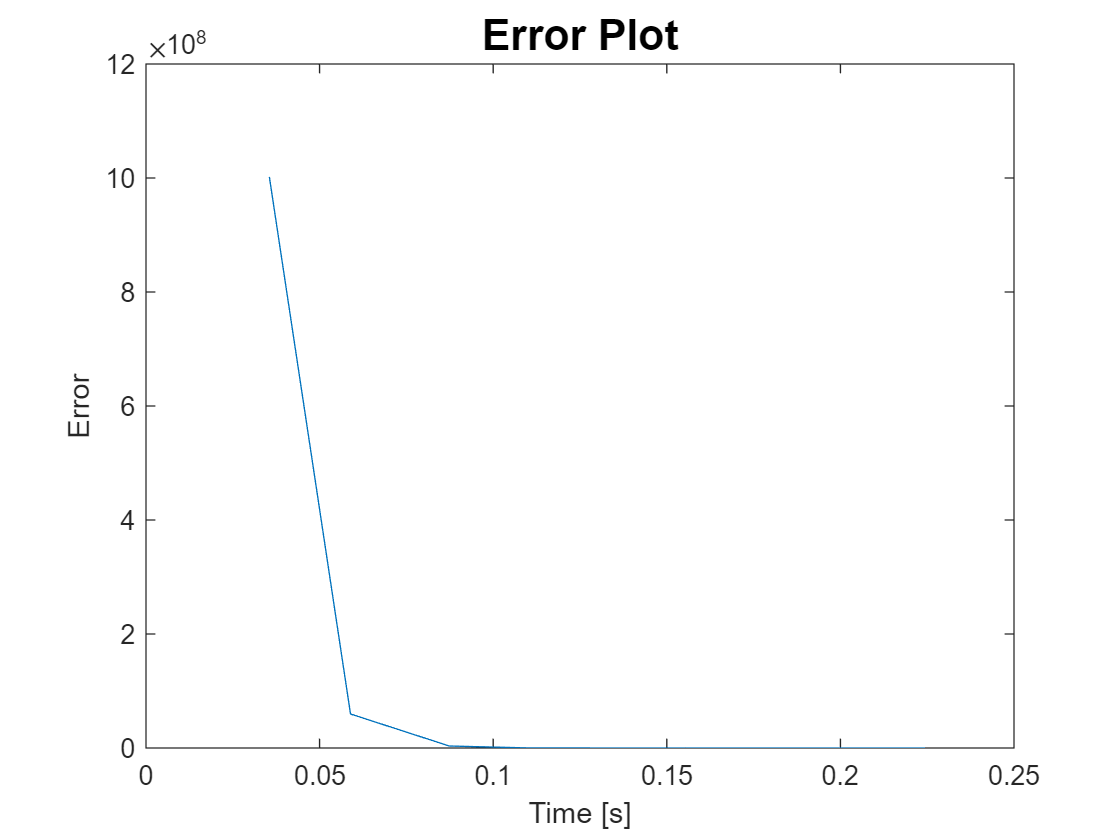

plot(timeCostseq, err_fseq)
title('Error Plot','FontSize',16)
xlabel('Time [s]')
ylabel('Error')

loglog(timeCostseq, err_fseq)  % base-10 logarithmic scale on the x-axis and the y-axis
title('Logaritmic Error Plot','FontSize',16)
xlabel('Time [s]')
ylabel('Error')